# RL agent v2.4.1 Test

DQN without recurring neural network

Creating first environment

env = modelEnv241;
obs = getObservationInfo(env);
acts = getActionInfo(env);
rng(0)
format shortG
validateEnvironment(env)

Initial training

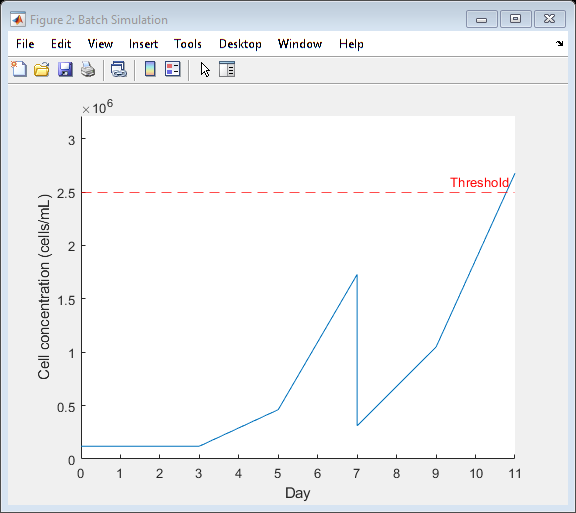

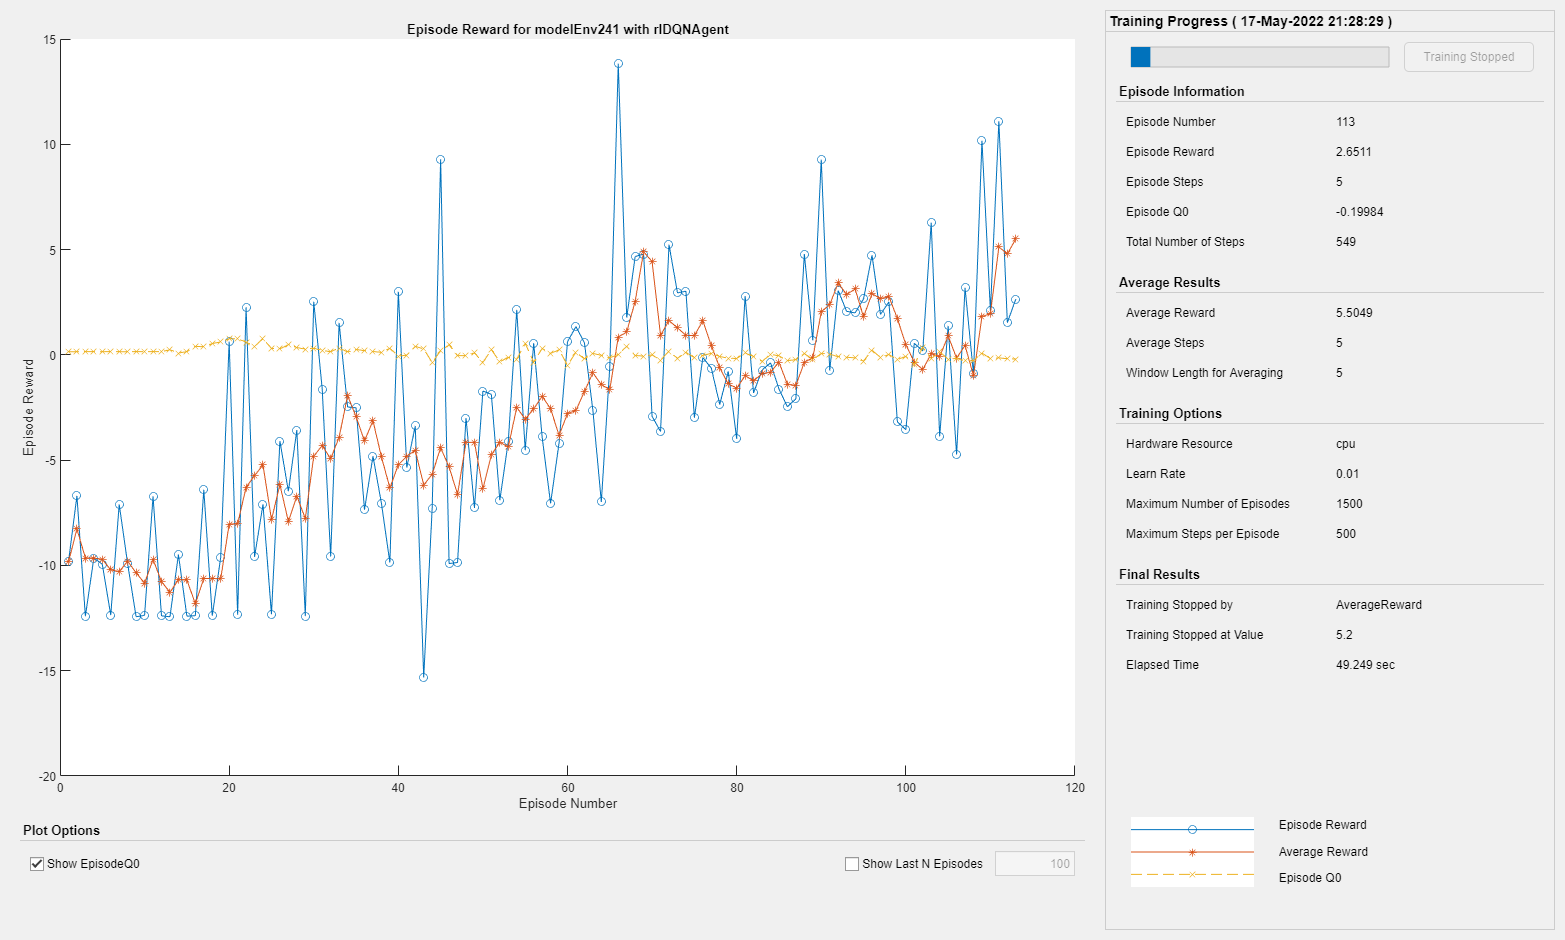

rng(0)
% hyperparameters
discountFactor = 1;
epsilon = 1;

initOpts = rlAgentInitializationOptions;
initOpts.NumHiddenUnit = 64;
initOpts.UseRNN = false;

dqnagentoptions = rlDQNAgentOptions;
dqnagentoptions.DiscountFactor = discountFactor;
dqnagentoptions.EpsilonGreedyExploration.Epsilon = epsilon;
dqnagentoptions.SequenceLength = 1;
dqnagentoptions.UseDoubleDQN = false;

dqnagent = rlDQNAgent(obs,acts,initOpts,dqnagentoptions);
% plot(layerGraph(getModel(getCritic(dqnagent)).Layers));

trainopts = rlTrainingOptions;
trainopts.MaxEpisodes = 1500;
trainopts.StopTrainingCriteria = "AverageReward";
trainopts.StopTrainingValue = 5.2;
%trainopts.Plots = 'none';
%trainopts.Verbose = true;

plot(env)
results = train(dqnagent,env,trainopts);